# visualizing delta_b(t)

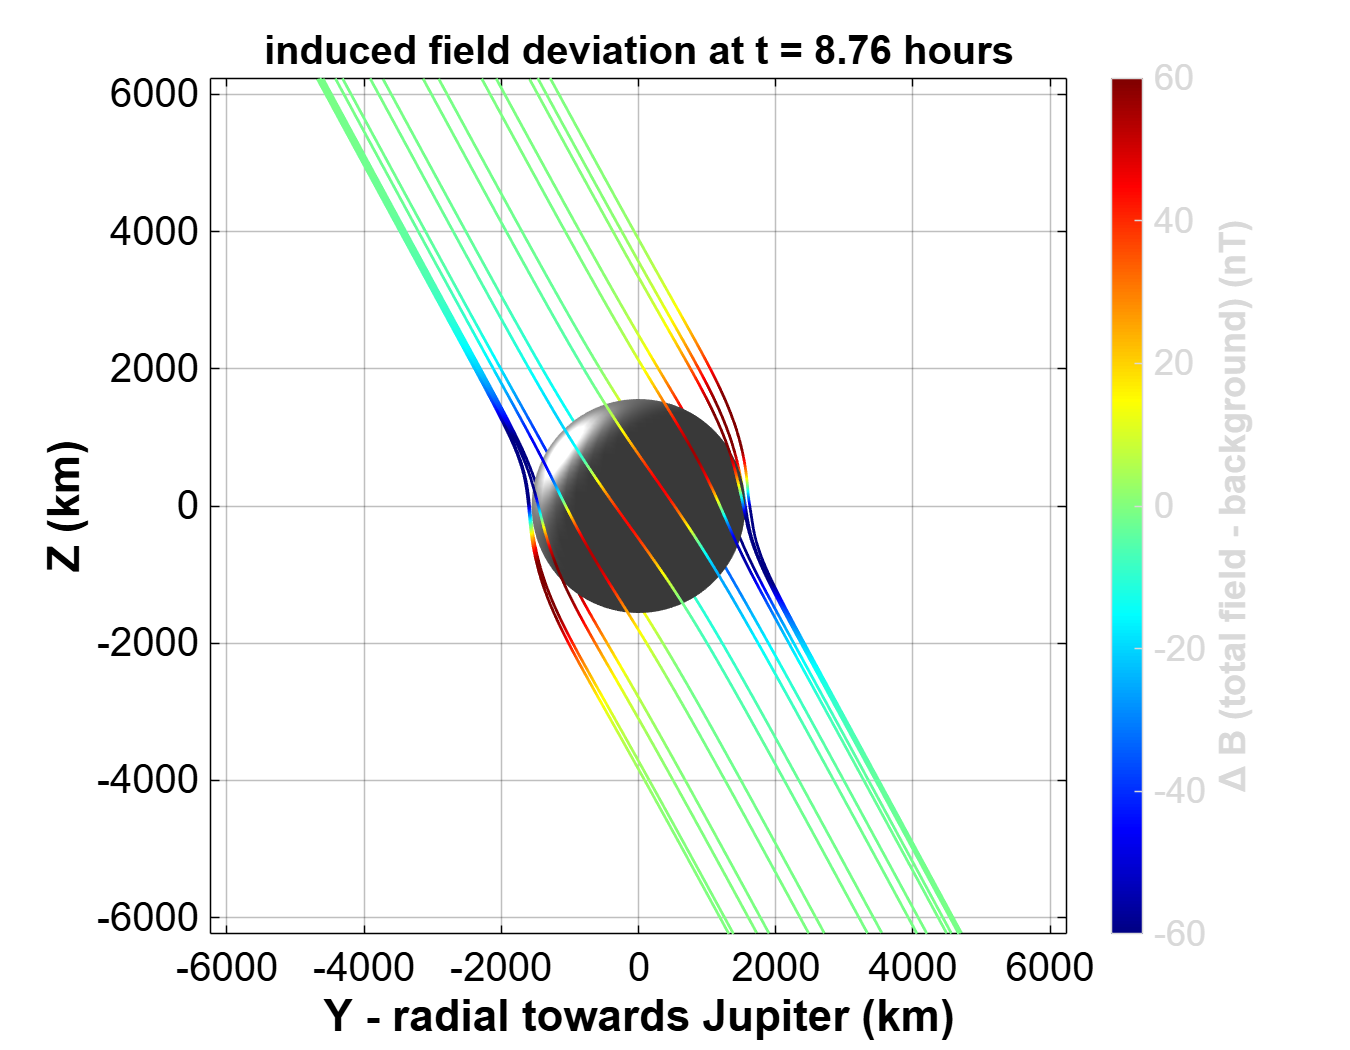

clear
% define constants
r_m = 1560; % Europa radius (km)
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / (synodic_period); % synodic freq. (rad/sec)

% elliptical primary field amplitudes from Zimmer's range (IS-system)
Bprim_x_amp = 67;  % azimuthal (orbital travel direction)
Bprim_y_amp = 225; % radial (pointing toward Jupiter)
Bprim_z_amp = 410;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create spatial grid
grid_limit = 4 * r_m; 
num_points = 70;       
[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points));

R = sqrt(X.^2 + Y.^2 + Z.^2);
mask = R >= r_m; 

% set up animation time array
num_frames = 60;
time_steps = linspace(0, synodic_period, num_frames);

fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 700]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% animation loop 
for t = time_steps

    r_dot_e0x = X; 
    r_dot_e0y = Y; 

    % complex secondary field: x-driven 
    coefx_c = -(A * Bprim_x_amp * r_m^3) .* exp(-1i*(omega * t - phi)) ./ (2 * R.^5);
    Bsecx_x = coefx_c .* (3 * r_dot_e0x .* X - R.^2);
    Bsecx_y = coefx_c .* (3 * r_dot_e0x .* Y);
    Bsecx_z = coefx_c .* (3 * r_dot_e0x .* Z);

    % complex secondary field: y-driven (90 deg / pi/2 shifted)
    coefy_c = -(A * Bprim_y_amp * r_m^3) .* exp(-1i*(omega*t - pi/2 - phi)) ./ (2 * R.^5);
    Bsecy_x = coefy_c .* (3 * r_dot_e0y .* X);
    Bsecy_y = coefy_c .* (3 * r_dot_e0y .* Y - R.^2);
    Bsecy_z = coefy_c .* (3 * r_dot_e0y .* Z);

    % complex primary background field
    Bprim_c_x = Bprim_x_amp * exp(-1i*omega*t);
    Bprim_c_y = Bprim_y_amp * exp(-1i*(omega*t - pi/2));
    Bprim_c_z = Bprim_z_amp;

    % superimpose total field fields and take real components
    Bx = real(Bsecx_x + Bsecy_x + Bprim_c_x);
    By = real(Bsecx_y + Bsecy_y + Bprim_c_y);
    Bz = real(Bsecx_z + Bsecy_z + Bprim_c_z);

    % calculate total field magnitude 
    B_mag = sqrt(Bx.^2 + By.^2 + Bz.^2);

    % calculate background magnitude components for this specific frame
    Bx_p = real(Bprim_c_x);
    By_p = real(Bprim_c_y);
    Bz_p = real(Bprim_c_z);
    B_prim_mag_now = sqrt(Bx_p^2 + By_p^2 + Bz_p^2);
    
    % subtract it to isolate the physical induced field features
    B_deviation = B_mag - B_prim_mag_now;

    % zero interior field matrix for streamline propagation
    Bx(~mask) = 0;
    By(~mask) = 0;
    Bz(~mask) = 0;

    % dynamic equator tracking from total primary field directions
    Bx_prim_now = real(Bprim_c_x);
    By_prim_now = real(Bprim_c_y);
    Bz_prim_now = real(Bprim_c_z);
    
    % find instantaneous alignment vector of the primary driving force
    m_real = [Bx_prim_now; By_prim_now; Bz_prim_now];
    m_hat = m_real / norm(m_real);

    % seed rings 
    v1 = cross(m_hat, [0; 0; 1]);
    if norm(v1) < 1e-6         
        v1 = cross(m_hat, [1; 0; 0]);
    end
    v1 = v1 / norm(v1);
    v2 = cross(m_hat, v1);      % guaranteed perpendicular to both m_hat and v1
    v2 = v2 / norm(v2);
    
    num_seeds_per_ring = 16;
    theta = linspace(0, 2*pi, num_seeds_per_ring);
    
    % shells
    radii_layers = 1.1 * r_m;
    
    total_seeds = length(radii_layers) * num_seeds_per_ring;
    seed_X = zeros(1, total_seeds);
    seed_Y = zeros(1, total_seeds);
    seed_Z = zeros(1, total_seeds);
    
    idx = 1;
    for r_seed = radii_layers
        for k = 1:length(theta)
            pt = r_seed * (cos(theta(k))*v1 + sin(theta(k))*v2);
            seed_X(idx) = pt(1);
            seed_Y(idx) = pt(2);
            seed_Z(idx) = pt(3);
            idx = idx + 1;
        end
    end
   
    clf;
    set(gcf, 'Color', 'w');
    
    % Europa
    [sx, sy, sz] = sphere(50);
    surf(sx*r_m, sy*r_m, sz*r_m, 'FaceColor', [0.75 0.75 0.75], ...
         'EdgeColor', 'none', 'FaceAlpha', 1.0);


    hold on;
    camlight('headlight'); lighting gouraud;

    verts_forward = stream3(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    verts_backward = stream3(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));

    % draw stitched streamlines using the surface gradient trick
    for k = 1:num_seeds_per_ring
        v_f = verts_forward{k};
        v_b = verts_backward{k};
        
        if isempty(v_f) && isempty(v_b)
            continue;
        elseif isempty(v_f)
            v = v_b;
        elseif isempty(v_b)
            v = v_f;
        else
            % flip backward lines to run into the seed point then join with forward
            v = [flipud(v_b); v_f];
        end

        % sample the field deviation along the paths for dynamic contrast tracking
        line_colors = interp3(X, Y, Z, B_deviation, v(:,1), v(:,2), v(:,3));

        % create a 2-row surface grid for point by point gradients without patch bug
        surf_x = [v(:,1)'; v(:,1)'];
        surf_y = [v(:,2)'; v(:,2)'];
        surf_z = [v(:,3)'; v(:,3)'];
        surf_c = [line_colors'; line_colors'];

        surface(surf_x, surf_y, surf_z, surf_c, ...
                'FaceColor', 'none', ...
                'EdgeColor', 'interp', ...
                'LineWidth', 1.4);
    end
    
    colormap(jet);
    c = colorbar;
    ylabel(c, '\Delta B (total field - background) (nT)', 'FontWeight', 'bold');

    % lock the colorbar to a static high-contrast deviation range
    clim([-60, 60]); 

    axis equal; grid on; box on;
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);
    
    ax = gca;
    set(ax, 'XColor', 'k', 'YColor', 'k', 'FontSize', 20, 'ZColor', 'k', 'Color', 'w');
    xlabel('X - azimuthal \phi (km)', 'FontWeight', 'bold');
    ylabel('Y - radial towards Jupiter (km)', 'FontWeight', 'bold');
    zlabel('Z (km)', 'FontWeight', 'bold');

    view([90 0]); 
    title(sprintf('induced field deviation at t = %.2f hours', t/3600), ...
          'Color', 'k', 'FontSize', 20 , 'FontWeight', 'bold');

    drawnow;
    pause(0.04);
end